Read the original image

originalImage = imread("jpg/image.png");

Check if the image has channels

if size(originalImage, 3) == 1;
    display('Display image, no channels!');
end;

Split images into channels 

redChannel = originalImage(:, :, 1);
greenChannel = originalImage(:, :, 2);
blueChannel = originalImage(:, :, 3);

Display images 

figure;

Display orginal image

subplot(2,2,1);
imshow(originalImage);
title("Original Image");

Display red channel

subplot(2,2,2);
imshow(redChannel);
title("Red Channel");
%colormap('parula');

Display green channel

subplot(2,2,3);
imshow(greenChannel);
title("Green Channel");
%colormap('parula');

Display blue channel

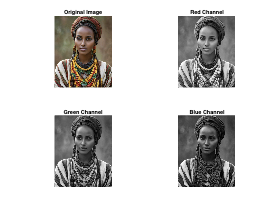

subplot(2,2,4);
imshow(blueChannel);
title("Blue Channel")

%colormap('parula');

HSV image conversion

hsvImage = rgb2hsv(originalImage);

Extract each channel 

hueChannel = hsvImage(:, :, 1);
saturationChannel = hsvImage(:, :, 2);
valueChannel = hsvImage(:, :, 3);

Display in figure 

figure;

Display Hue channel 

subplot(1,3,1);
imshow(hueChannel);
title("Hue channel");
%colormap("hsv");

Display saturation channel 

subplot(1,3,2);
imshow(saturationChannel);
title("Saturation channel");
%colormap("hsv");

Display vlaue channel

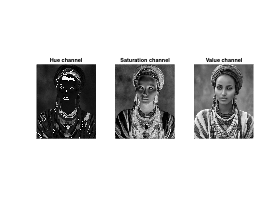

subplot(1,3,3);
imshow(valueChannel);
title("Value channel");

%colormap("hsv");

Enlarge image to twice the size

resizedImage = imresize(originalImage, 2);

Display orginal image and resized

figure;

Display the original image

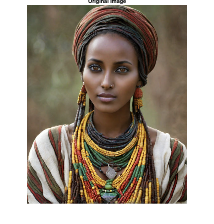

imshow(originalImage);
title("Original Image");

Display the resized image

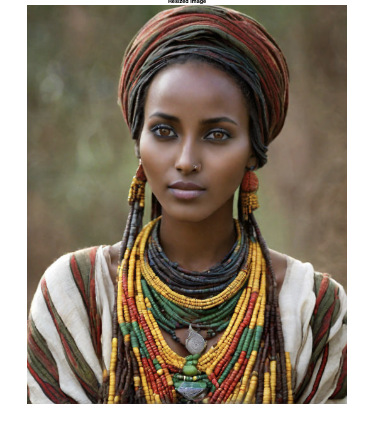

imshow(resizedImage);
title("Resized Image");

Crop the resized image

originalSize = size(originalImage);
croppedImage = imcrop(resizedImage, [1, 1, originalSize(2)-1, originalSize(1)-1]);

Display the cropped image

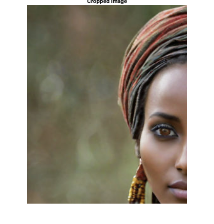

figure;
imshow(croppedImage);
title("Cropped Image");

Convert original image to grayscale

grayImage = rgb2gray(originalImage);

Display the grayscale image

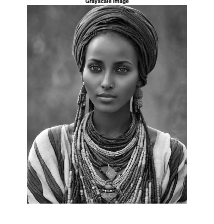

figure;
imshow(grayImage);
title("Grayscale Image");

Generate Histogram of the grayscale image

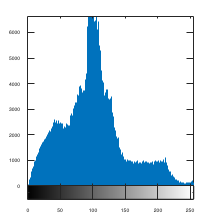

imhist(grayImage);

Histogram matching test

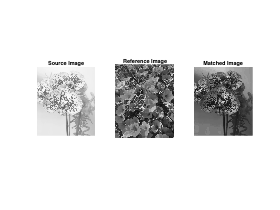

Histogram matching completed.


sourceImage = imread('jpg/src.png');
referenceImage = imread('jpg/ref.png');
outputFilePath = 'jpg/matched_image_result.png';

matchedImage = histogramMatching(sourceImage, referenceImage, outputFilePath);

Display the histogram of the original and the matched

figure;

Histogram of grayscale image

subplot(1,3,1);
imhist(sourceImage);
title("Grayscale Image");

Histogram of the refernece image

subplot(1,3,2);
imhist(referenceImage);
title("Reference Image");

Histogram of the matched image

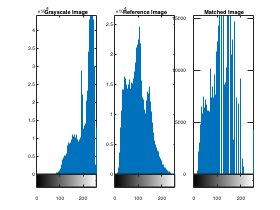

subplot(1,3,3);
imhist(matchedImage);
title("Matched Image");

Histogram matching function

function matchedImage = histogramMatching(sourceImage, referenceImage, outputPath)
    % Handle color images for both source and reference inputs
    if size(sourceImage, 3) == 3
        sourceImage = rgb2gray(sourceImage);
    end

    if size(referenceImage, 3) == 3
        referenceImage = rgb2gray(referenceImage);
    end

    % Histogram matching
    matchedImage = histeq(sourceImage, imhist(referenceImage));

    % Save matched image
    imwrite(matchedImage, outputPath);

    % Display images
    figure;

    % Display source image
    subplot(1, 3, 1);
    imshow(sourceImage);
    title('Source Image');

    % Display reference image
    subplot(1, 3, 2);
    imshow(referenceImage);
    title('Reference Image');

    % Display matched image
    subplot(1, 3, 3);
    imshow(matchedImage);
    title('Matched Image');

    % Save image as an image file
    saveas(gcf, 'histogram_matching.png');

    % End of function alert
    disp('Histogram matching completed.');
end